# Operating point




V_vsc_mag=1.005;P_t=P_aero_0;x_sys=0.8768

x_sys = 0.8768

delta_vsc_0=asin((x_sys*P_t/V_vsc_mag))

delta_vsc_0 = 0.5509

delta_vsc_0*180/pi

ans = 31.5648

V_vsc=V_vsc_mag*(cos(delta_vsc_0)+i*sin(delta_vsc_0))

V_vsc = 0.8563 + 0.5261i

Q_t=(V_vsc_mag^2-cos(delta_vsc_0))/x_sys

Q_t = 0.1802

I_vsc=conj((P_t+i*Q_t))/(V_vsc_mag*(cos(delta_vsc_0)-i*sin(delta_vsc_0)))

I_vsc = 0.6025 + 0.1598i

angle(I_vsc);ans*180/pi

ans = 14.8503

abs(I_vsc)

ans = 0.6234

V_t=V_vsc_mag*(cos(delta_vsc_0)+i*sin(delta_vsc_0))+i*0.1056*I_vsc

V_t = 0.8394 + 0.5897i

delta_t=angle(V_t); delta_t*180/pi

ans = 35.0881

V_t_mag=abs(V_t)

V_t_mag = 1.0259



v_D0_vsc =real(V_vsc), v_Q0_vsc = imag(V_vsc)

v_D0_vsc = 0.8563

v_Q0_vsc = 0.5261

i_D0_vsc = real(I_vsc), i_Q0_vsc = imag(I_vsc)

i_D0_vsc = 0.6025

i_Q0_vsc = 0.1598

v_d0_t = real(V_t), v_q0_t = imag(V_t)

v_d0_t = 0.8394

v_q0_t = 0.5897

theta_0_vsc = 0.8354107558;


% dq/DqQ transformation matrices
P_meas = [v_D0_vsc v_Q0_vsc i_D0_vsc i_Q0_vsc]

P_meas =     0.8563    0.5261    0.6025    0.1598


Q_meas = [v_Q0_vsc -v_D0_vsc -i_Q0_vsc i_D0_vsc]

Q_meas =     0.5261   -0.8563   -0.1598    0.6025


v_D_t = [-v_q0_t*sin(delta_vsc_0)+v_d0_t*cos(delta_vsc_0) cos(delta_vsc_0) sin(delta_vsc_0) ]

v_D_t =     0.4066    0.8520    0.5235


v_Q_t = [-v_d0_t*cos(delta_vsc_0)-v_q0_t*sin(delta_vsc_0) -sin(delta_vsc_0) cos(delta_vsc_0) ]

v_Q_t =    -1.0239   -0.5235    0.8520


v_d_vsc = [-v_Q0_vsc*sin(delta_vsc_0)-v_D0_vsc*cos(delta_vsc_0) cos(delta_vsc_0) -sin(delta_vsc_0) ]

v_d_vsc =    -1.0050    0.8520   -0.5235


v_q_vsc = [v_D0_vsc*cos(delta_vsc_0)-v_Q0_vsc*sin(delta_vsc_0) sin(delta_vsc_0) cos(delta_vsc_0) ]

v_q_vsc =     0.4542    0.5235    0.8520


i_d_vsc = [-i_Q0_vsc*sin(delta_vsc_0)-i_D0_vsc*cos(delta_vsc_0) cos(delta_vsc_0) -sin(delta_vsc_0) ]

i_d_vsc =    -0.5970    0.8520   -0.5235


i_q_vsc = [i_D0_vsc*cos(delta_vsc_0)-i_Q0_vsc*sin(delta_vsc_0) sin(delta_vsc_0) cos(delta_vsc_0) ]

i_q_vsc =     0.4298    0.5235    0.8520



T_vdq_DQ = [v_D_t; v_Q_t]

T_vdq_DQ =     0.4066    0.8520    0.5235
   -1.0239   -0.5235    0.8520


T_vDQ_dq = [v_d_vsc; v_q_vsc]

T_vDQ_dq =    -1.0050    0.8520   -0.5235
    0.4542    0.5235    0.8520


T_iDQ_dq = [i_d_vsc; i_q_vsc]

T_iDQ_dq =    -0.5970    0.8520   -0.5235
    0.4298    0.5235    0.8520



T_PQ_meas = [P_meas; Q_meas]

T_PQ_meas =     0.8563    0.5261    0.6025    0.1598
    0.5261   -0.8563   -0.1598    0.6025


## p/angle controller



% k_d_vsm=70
% 
% H_vsm = 3.5
T_vsm = tf([omega_nom/(2*H_vsm*x_sys)*cos(delta_vsc_0)],[1 k_d_vsm/(2*H_vsm) omega_nom/(2*H_vsm*x_sys)*cos(delta_vsc_0)])

T_vsm =
 
          50.88
  ---------------------
  s^2 + 11.67 s + 50.88
 
Continuous-time transfer function.
Model Properties



G_vsm = omega_nom/(2*H_vsm*s+k_d_vsm)

G_vsm =
 
   314.2
  --------
  6 s + 70
 
Continuous-time transfer function.
Model Properties



zeta_vsm = k_d_vsm/H_vsm*sqrt(2*H_vsm*x_sys/omega_nom)

zeta_vsm = 3.0194

nf_vsm = sqrt(omega_nom/(2*H_vsm*x_sys))

nf_vsm = 7.7277

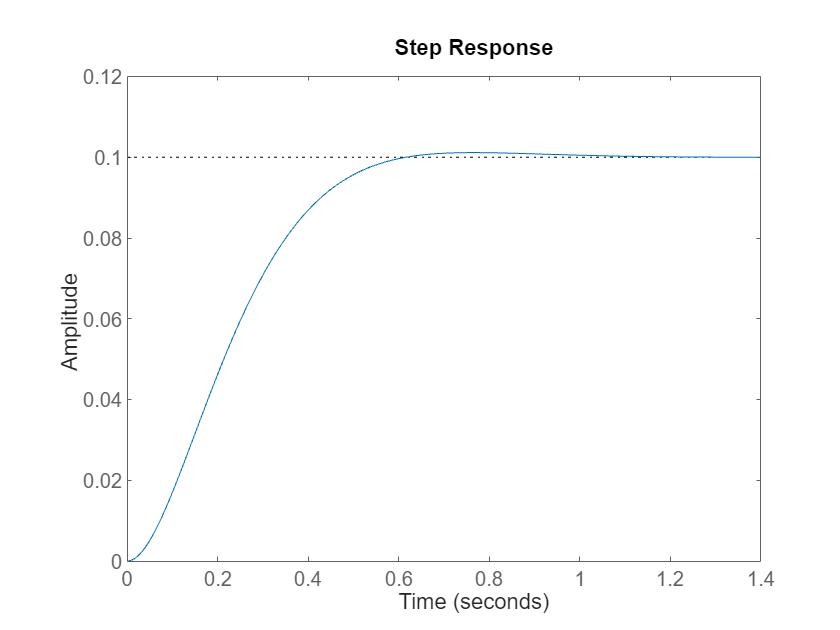

step(T_vsm*0.1)

## q controller droop


ki_q

ki_q = 314.1593

k_p_q_vsm = -0.05

k_p_q_vsm = -0.0500


% open loop

%closed loop 
T_q_vsm = tf([ki_q*k_p_q_vsm/x_sys],[1 ki_q+k_p_q_vsm*ki_q/x_sys])

T_q_vsm =
 
   -17.92
  ---------
  s + 296.2
 
Continuous-time transfer function.
Model Properties



%open loop Q_grid -> delta V_d_ref
G_qdroop = tf([ki_q*k_p_q_vsm],[1 ki_q])

G_qdroop =
 
   -15.71
  ---------
  s + 314.2
 
Continuous-time transfer function.
Model Properties


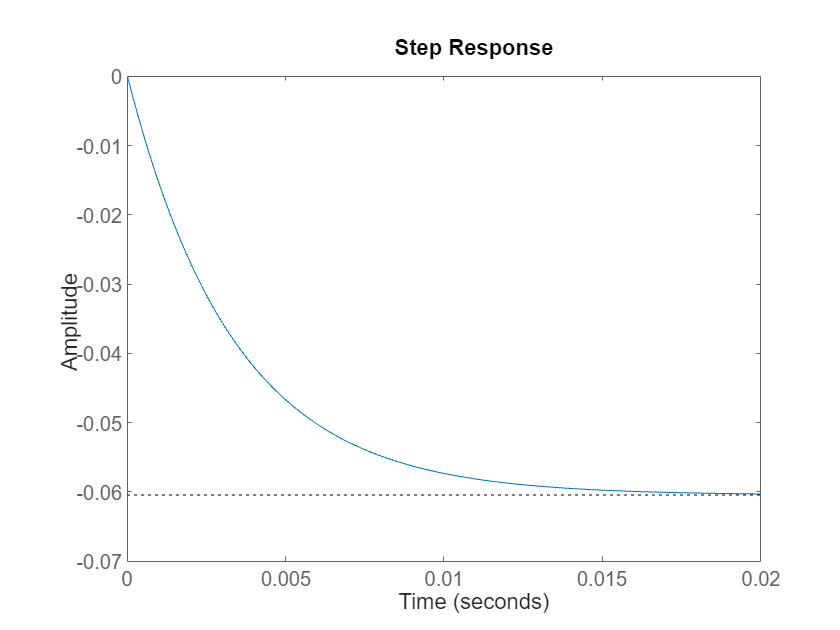


step(T_q_vsm)

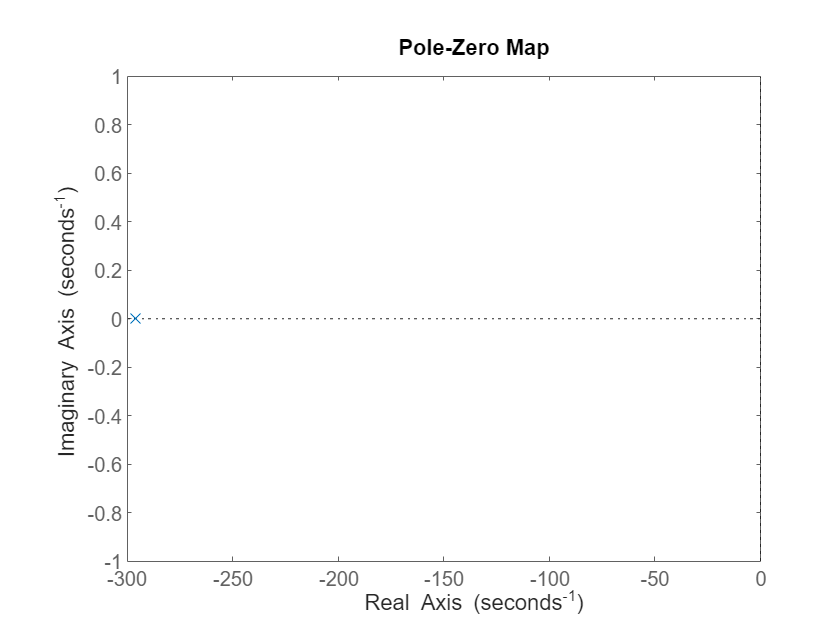

% step(T_e_vsm)

pzmap(T_q_vsm)

## current control

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


ti = 5/f_sw

ti = 0.0017

G_plant = 1/(s*l_f/omega_nom+r_f)

G_plant =
 
       314.2
  ----------------
  0.1056 s + 1.658
 
Continuous-time transfer function.
Model Properties


kp = (l_f/omega_nom)/ti

kp = 0.1983

ki = r_f/ti

ki = 3.1145

G_cc = (kp*s+ki)/s

G_cc =
 
  0.1983 s + 3.115
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_cc = G_plant*G_cc/(1+G_plant*G_cc)

T_cc =
 
         6.577 s^3 + 206.6 s^2 + 1623 s
  --------------------------------------------
  0.01115 s^4 + 6.927 s^3 + 209.4 s^2 + 1623 s
 
Continuous-time transfer function.
Model Properties



tf2ss([kp ki], [1 0])

ans = 0

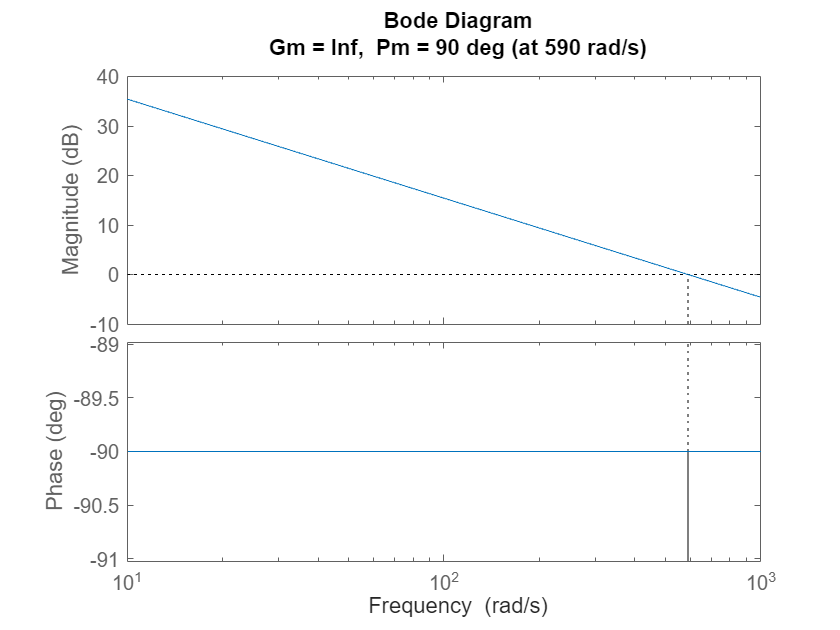

margin(G_plant*G_cc)

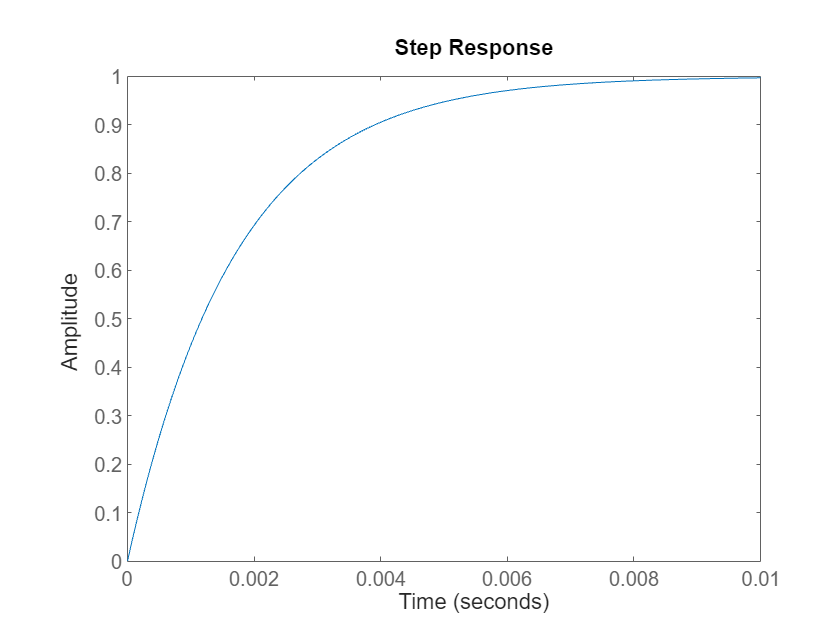

step(T_cc)

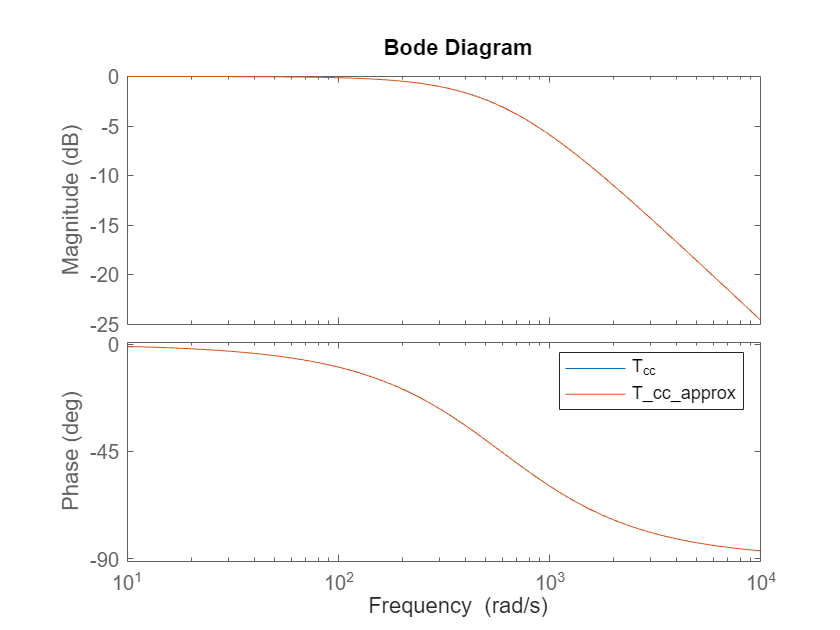

bode(T_cc,1/(ti*s+1))
legend('T_cc', 'T_cc_approx')

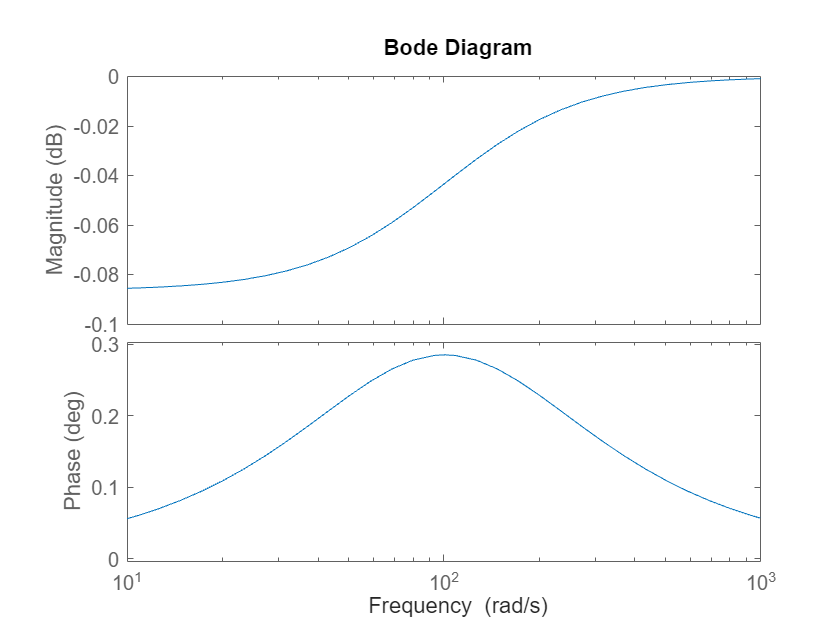

bode(((0.01*s+1)/0.01)/(1+(0.01*s+1)/0.01)) 



G_plant = 1/(s*l_f/omega_nom+r_f)

G_plant =
 
       314.2
  ----------------
  0.1056 s + 1.658
 
Continuous-time transfer function.
Model Properties


G_grid_plant = 1/(s*x_sys/omega_nom+r_grid)

G_grid_plant =
 
       314.2
  ----------------
  0.8768 s + 33.12
 
Continuous-time transfer function.
Model Properties


% dq tf 
i_DQ_plant = [1/G_plant -l_f;
              l_f 1/G_plant]

i_DQ_plant =
 
  From input 1 to output...
       0.1056 s + 1.658
   1:  ----------------
            314.2
 
   2:  0.1056
 
  From input 2 to output...
   1:  -0.1056
 
       0.1056 s + 1.658
   2:  ----------------
            314.2
 
Continuous-time transfer function.
Model Properties


i_dq_ctrl = eye(2,2)*G_cc

i_dq_ctrl =
 
  From input 1 to output...
       0.1983 s + 3.115
   1:  ----------------
              s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       0.1983 s + 3.115
   2:  ----------------
              s
 
Continuous-time transfer function.
Model Properties


 i_dq_ff = [0 -l_f;
            l_f 0]

i_dq_ff =          0   -0.1056
    0.1056         0


i_DQ_grid = [1/G_grid_plant -x_sys;
              x_sys  1/G_grid_plant]

i_DQ_grid =
 
  From input 1 to output...
       0.8768 s + 33.12
   1:  ----------------
            314.2
 
   2:  0.8768
 
  From input 2 to output...
   1:  -0.8768
 
       0.8768 s + 33.12
   2:  ----------------
            314.2
 
Continuous-time transfer function.
Model Properties


## voltage control



z = 20

z = 20

asind((1-ti*z)/(1+ti*z)) % phase margin

ans = 69.1356

omega_c_vc = sqrt(z/ti)

omega_c_vc = 108.6278

k_vc = (c_f/omega_nom)*omega_c_vc

k_vc = 0.0262

G_vc = k_vc*(s+z)/s

G_vc =
 
  0.02618 s + 0.5235
  ------------------
          s
 
Continuous-time transfer function.
Model Properties


%open
G_forward_vc = k_vc/(ti*(c_f/omega_nom))*((s+z)/(s+1/ti))*1/s^2

G_forward_vc =
 
  6.409e04 s + 1.282e06
  ---------------------
      s^3 + 590 s^2
 
Continuous-time transfer function.
Model Properties


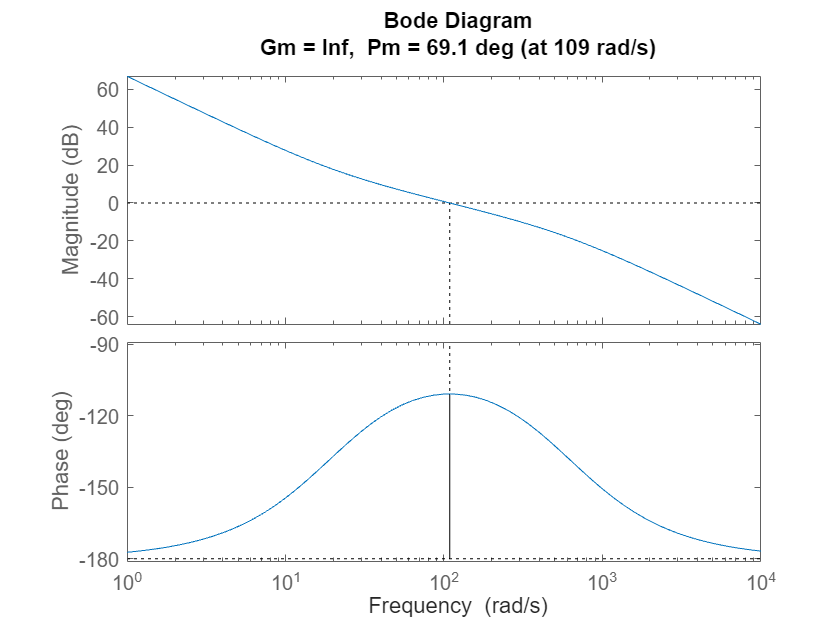

margin(G_forward_vc)

% closed
T_vc = k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2/(1+k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2)

T_vc =
 
          2.338e05 s^4 + 1.426e08 s^3 + 2.759e09 s^2
  -----------------------------------------------------------
  s^6 + 1180 s^5 + 5.819e05 s^4 + 1.426e08 s^3 + 2.759e09 s^2
 
Continuous-time transfer function.
Model Properties


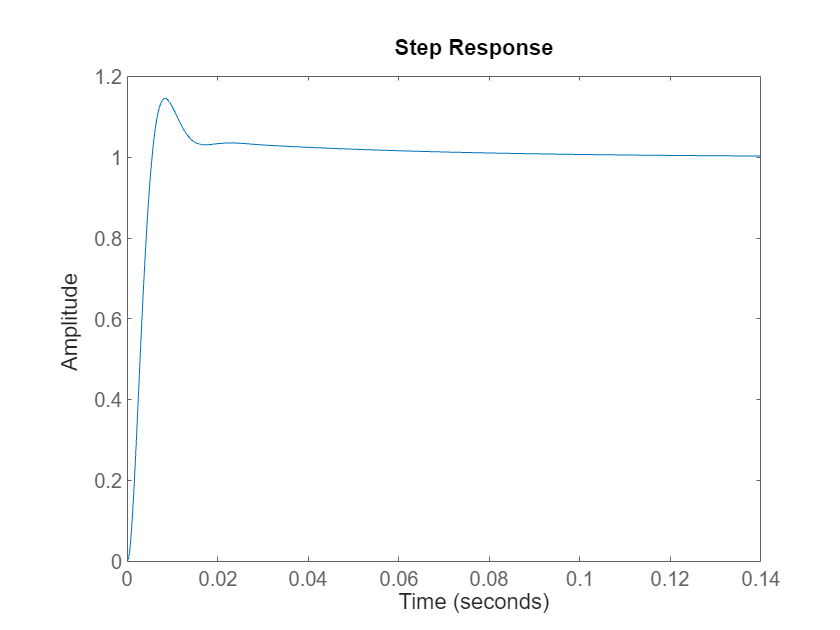

    step(T_vc)

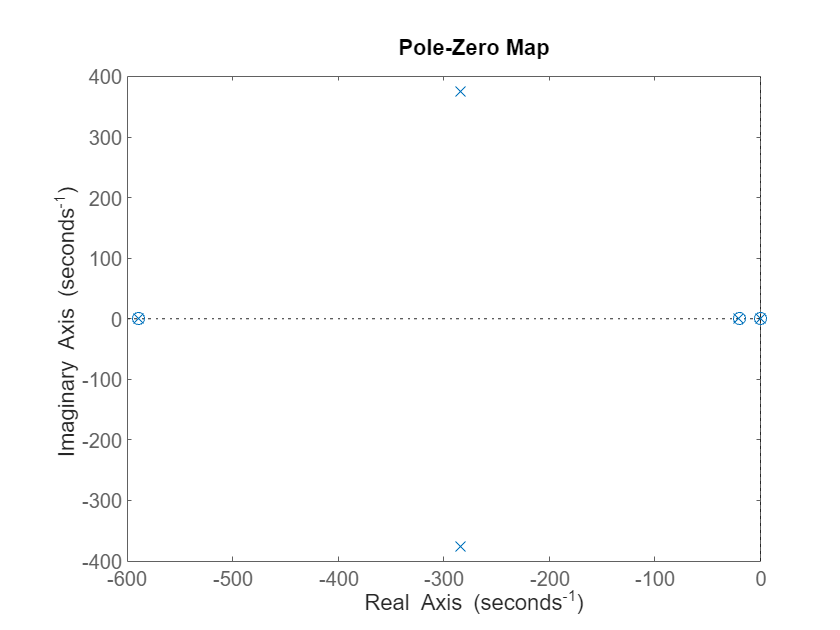

    pzmap(T_vc)


 v_DQ_plant = [s*c_f/omega_nom -c_f;
                c_f s*c_f/omega_nom]

v_DQ_plant =
 
  From input 1 to output...
       0.0757 s
   1:  --------
        314.2
 
   2:  0.0757
 
  From input 2 to output...
   1:  -0.0757
 
       0.0757 s
   2:  --------
        314.2
 
Continuous-time transfer function.
Model Properties


 v_dq_ctrl = eye(2,2)*G_vc

v_dq_ctrl =
 
  From input 1 to output...
       0.02618 s + 0.5235
   1:  ------------------
               s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       0.02618 s + 0.5235
   2:  ------------------
               s
 
Continuous-time transfer function.
Model Properties


 v_dq_ff = [0 -c_f;
            c_f 0]

v_dq_ff =          0   -0.0757
    0.0757         0


## Detailed dc voltage controller

% 
% c_dc =0.00666540000000 % pu  0.47 % aggregated
% % negative 1 is steady state wind power pu
% % cross over frequency is 20 rad/s
%     zigma_dc = 2*l_f*(1)/(3*1^2)
% k0 = 1.5
% G_dc_pre =-k0*2/c_dc*(zigma_dc*s+1)/(s^2*(0.01*s+1)) 
% margin(G_dc_pre)
% step(G_dc_pre/(1+G_dc_pre))
% 
% n0 = 1/(10^(-13/20));
% 
% a = 50; 
% asind((a-1)/(a+1)) % phase margin
% p = sqrt(a)*23;
% N = -n0*(s+p/a)/(s+p)
% bode(N,N*G_dc_pre)
% margin(N*G_dc_pre)
% step(G_dc_pre*N/(1+G_dc_pre*N))
% 
% G_dc = N*k0/s 
% G_dc_num = get(G_dc,'Numerator')
% G_dc_denom = get(G_dc,'Denominator')
% T_dc = -2/c_f*(zigma_dc*s+1)/s
% T_dc_num = get(T_dc,'Numerator')
% T_dc_denom = get(T_dc,'Denominator')

##  dc voltage controller TV

% 
% C_dc_TV = 0.3 % F
% V_dc
% % negative 1 is steady state wind power pu
% % cross over frequency is 20 rad/s
% 
% G_dc_pre =1/(C_dc*s*V_dc) 
% margin(G_dc_pre)
% % step(G_dc_pre/(1+G_dc_pre))
% 
% kp_dc = 0.78;
% ki_dc = 0.85;
% margin(G_dc_pre*G_dc)
% G_dc = 1*(kp_dc + ki_dc/s)
% 
% 
% % a = 50; 
% % asind((a-1)/(a+1)) % phase margin
% % p = sqrt(a)*23;
% % N = -n0*(s+p/a)/(s+p)
% % bode(N,N*G_dc_pre)
% % margin(N*G_dc_pre)
% % step(G_dc_pre*N/(1+G_dc_pre*N))
% step(G_dc_pre*G_dc/(1+G_dc_pre*G_dc)*K_TP)
% G_dc_num = get(G_dc,'Numerator')
% G_dc_denom = get(G_dc,'Denominator')
% T_dc = G_dc_pre
% T_dc_num = get(T_dc,'Numerator')
% T_dc_denom = get(T_dc,'Denominator')

## simplified dc controller

c_dc = 0.47; % pu  aggregated
% cross over frequency is 20 rad/s
dc_plant = -1/(c_dc/omega_nom)*1/s

dc_plant =
 
  -668.4
  ------
    s
 
Continuous-time transfer function.
Model Properties


kp_dc = 0.07;
ki_dc = 0.2

ki_dc = 0.2000

G_dc = -1*(kp_dc + ki_dc/s)

G_dc =
 
  -0.07 s - 0.2
  -------------
        s
 
Continuous-time transfer function.
Model Properties


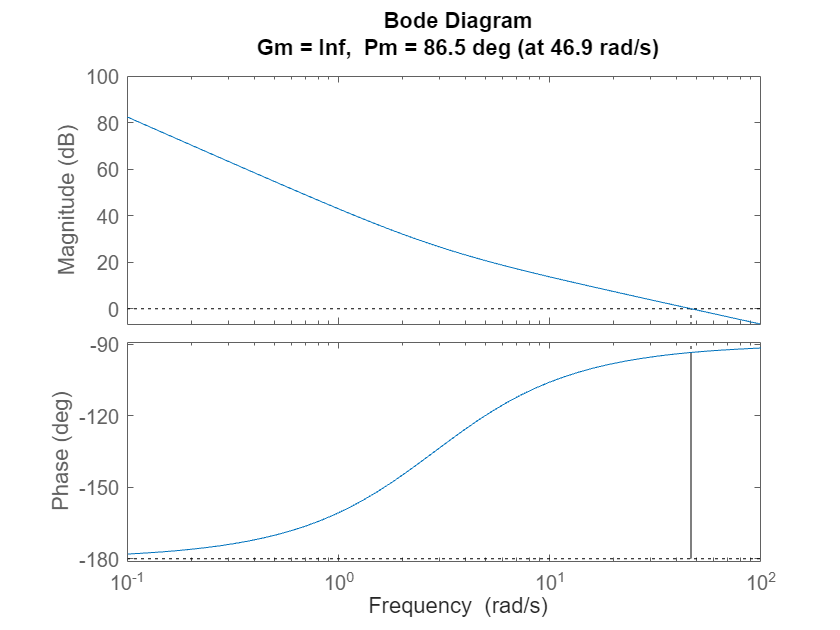


margin(G_dc*dc_plant)

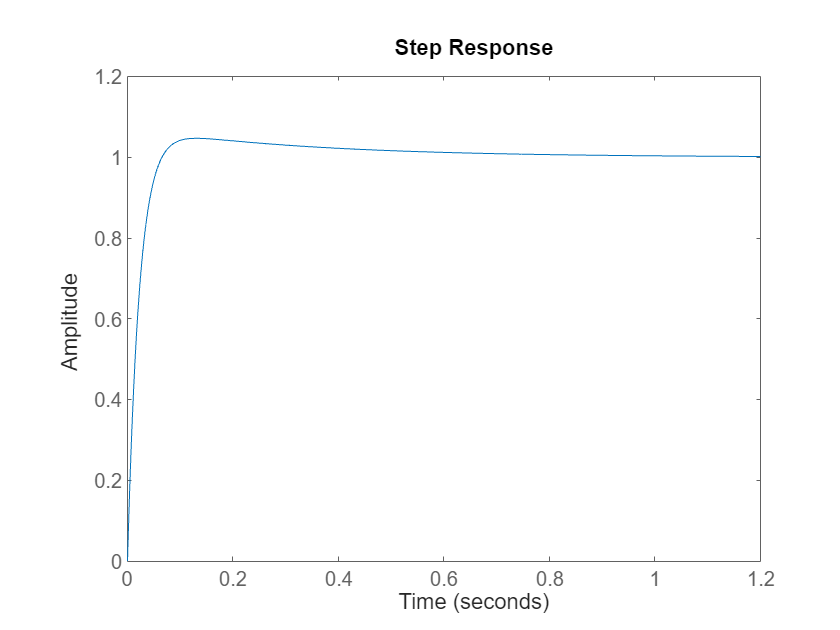

step(G_dc*dc_plant/(1+G_dc*dc_plant))


G_dc_num = get(G_dc,'Numerator')

G_dc_num = 1×1 cell array
    {[-0.0700 -0.2000]}


G_dc_denom = get(G_dc,'Denominator')

G_dc_denom = 1×1 cell array
    {[1 0]}


T_dc = dc_plant

T_dc =
 
  -668.4
  ------
    s
 
Continuous-time transfer function.
Model Properties


T_dc_num = get(T_dc,'Numerator')

T_dc_num = 1×1 cell array
    {[0 -668.4240]}


T_dc_denom = get(T_dc,'Denominator')

T_dc_denom = 1×1 cell array
    {[1 0]}


## Linearized mppt

omega_WTR_0*omega_WTR_n

ans = 0.6399

mppt_gain = 3/2*rho*pi*R_WTR^5*C_p_opt/lambda_opt^3*(omega_WTR_0*omega_WTR_n)^2

mppt_gain = 3.7182e+07

% torsional vibration paper
% v_w_TV = 10
% lambda_opt_TV = 7
% c_p_opt_TV = 0.44
% R_WTR_TV = 63
% omega_WTR_0_TV = v_w_TV*lambda_opt_TV/R_WTR_TV
% omega_WTR_0_TV/1.27

% 0.5*rho*pi*R_WTR_TV^2*c_p_opt_TV*v_w_TV^3
% 0.5*rho*pi*R_WTR_TV^2*c_p_opt_TV*(omega_WTR_0_TV*R_WTR_TV/lambda_opt_TV)^3

15*pi/180

ans = 0.2618

## Linearized two mass model

lambda_op = omega_WTR_0*R_WTR/(v_w_0*v_w_n)

lambda_op = 11.1156

k_tur=-0.04206446159

k_tur = -0.0421

A_m = 1/(2*H_WTR*s)

A_m =
 
    1
  -----
  4.2 s
 
Continuous-time transfer function.
Model Properties


A_g = 1/(2*H_gen*s)

A_g =
 
    1
  -----
  1.8 s
 
Continuous-time transfer function.
Model Properties


A_s = c_drt+k_drt/s

A_s =
 
  s + 280
  -------
     s
 
Continuous-time transfer function.
Model Properties



M_gr = A_s*((A_m*A_s)/(1+A_m*A_s-A_m*k_tur)-1)

M_gr =
 
  -74.09 s^6 - 2.075e04 s^5 - 207.8 s^4
  -------------------------------------
    74.09 s^6 + 18.38 s^5 + 4939 s^4
 
Continuous-time transfer function.
Model Properties


M_gr_num = get(M_gr,'Numerator')

M_gr_num = 1×1 cell array
    {[-74.0880 -2.0745e+04 -207.7648 0 0 0 0]}


M_gr_denom = get(M_gr,'Denominator')

M_gr_denom = 1×1 cell array
    {[74.0880 18.3820 4.9392e+03 0 0 0 0]}



K_Tomega = -P_aero_0/omega_WTR_0^2

K_Tomega = -0.9185

K_TP = 1/omega_WTR_0

K_TP = 1.2373

% Transfer functions

v_dq = [0; 0; G_vsm]

v_dq =
 
  From input to output...
   1:  0
 
   2:  0
 
        314.2
   3:  --------
       6 s + 70
 
Continuous-time transfer function.
Model Properties


v_DQ_t = T_vdq_DQ*v_dq

v_DQ_t =
 
  From input to output...
        164.5
   1:  --------
       6 s + 70
 
        267.7
   2:  --------
       6 s + 70
 
Continuous-time transfer function.
Model Properties


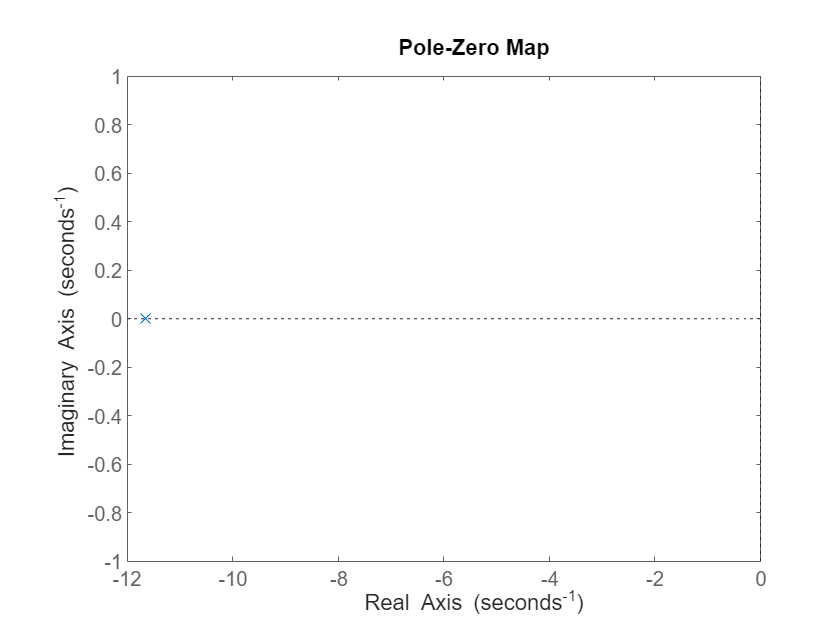


Ggrid = i_DQ_grid;
Gvplant = v_DQ_plant;
Giplant = i_DQ_plant;
pzmap(G_vsm)

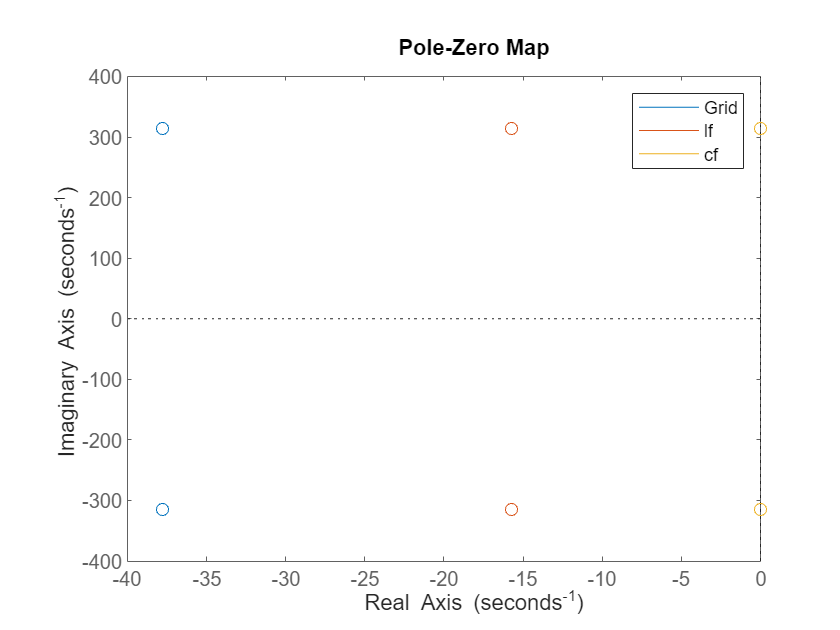

pzmap(Ggrid,Giplant,Gvplant)
legend Grid lf cf


% From v_DQ_t to v_DQ_vsc and i_DQ_vsc when v_Grid = 0


i_DQ_vsc = (-Ggrid*Gvplant + eye(2,2))/(-Ggrid*Gvplant + Ggrid + Giplant)*v_DQ_t % 

i_DQ_vsc =
 
  From input to output...
             986.7 s^9 - 1.36e07 s^8 + 6.307e10 s^7 - 9.591e13 s^6 - 2.795e16 s^5 + 5.791e19 s^4 + 9.177e22 s^3 + 1.435e25 s^2 + 9.025e27 s + 1.035e29
   1:  ------------------------------------------------------------------------------------------------------------------------------------------------------
       36 s^10 - 6.633e05 s^9 + 4.569e09 s^8 - 1.389e13 s^7 + 1.551e16 s^6 - 1.475e17 s^5 + 3.304e21 s^4 + 1.722e23 s^3 + 1.72e26 s^2 + 3.963e27 s + 2.304e28
 
               1606 s^9 - 2.214e07 s^8 + 9.74e10 s^7 - 1.047e14 s^6 - 1.92e17 s^5 + 2.29e20 s^4 - 3.375e22 s^3 + 2.266e25 s^2 - 3.259e27 s - 4.117e28
   2:  ------------------------------------------------------------------------------------------------------------------------------------------------------
       36 s^10 - 6.633e05 s^9 + 4.569e09 s^8 - 1.389e13 s^7 + 1.551e16 s^6 - 1.475e17 s^5 + 3.304e21 s^4 + 1.722e23 s^3 + 1.72e26 s^2 + 3.963e27 s + 2.304e28
 
Continuous-time transfer

v_DQ_vsc =  Ggrid*(-Ggrid*Gvplant + eye(2,2))/((-Ggrid*Gvplant + Ggrid + Giplant)*(Ggrid*Gvplant + eye(2,2)))*v_DQ_t %

v_DQ_vsc =
 
  From input to output...
                     4.095e06 s^16 - 5.374e10 s^15 + 2.442e14 s^14 - 4.99e17 s^13 + 9.011e20 s^12 - 1.982e24 s^11 + 1.58e27 s^10 - 2.415e30 s^9 + 2.677e33 s^8 + 1.196e36 s^7 + 2.267e39 s^6 + 2.129e42 s^5 + 6.145e44 s^4 + 3.735e47 s^3 + 4.275e49 s^2 + 1.673e52 s + 1.9e53
   1:  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
       36 s^18 - 6.579e05 s^17 + 4.698e09 s^16 - 1.738e13 s^15 + 4.246e16 s^14 - 9.193e19 s^13 + 1.553e23 s^12 - 1.86e26 s^11 + 2.785e29 s^10 - 1.527e32 s^9 + 2.476e35 s^8 - 4.022e37 s^7 + 1.006e41 s^6 + 3.322e42 s^5 + 1.446e46 s^4 + 7.676e47 s^3 + 6.41e50 s^2 + 1.474e52 s + 8.561e52
 
                   6.665e06 s^16 - 9.217e10 s^15 + 4.396e14 s^14 - 8.895e17 s^13 + 1.205e21 s^12 - 1.745e24 s^11 - 1.1

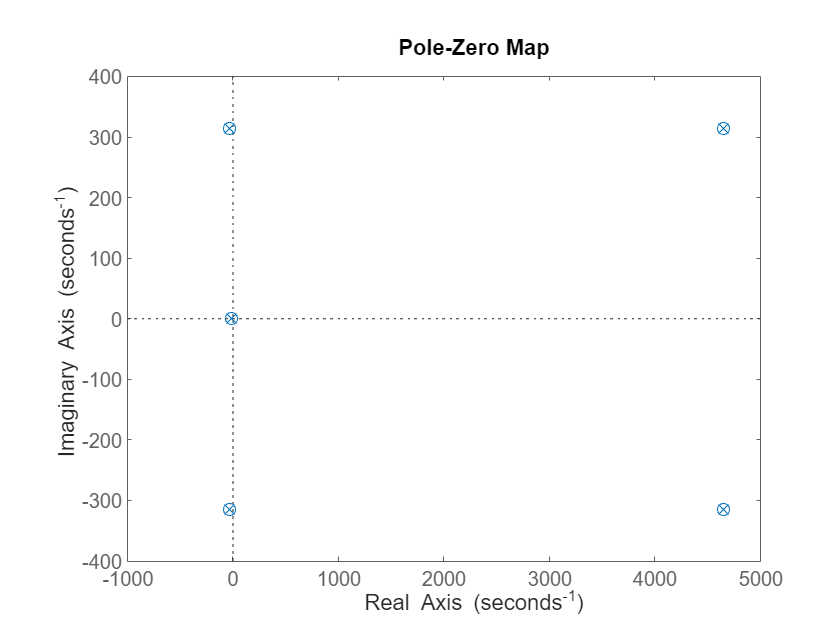


pzmap(i_DQ_vsc)

% pzmap(v_DQ_vsc)

% Forward gain from Pref to Pvsc
G_Pref_Pvsc = P_meas*[i_DQ_vsc; v_DQ_vsc]

G_Pref_Pvsc =
 
            7.884e07 s^55 - 5.256e12 s^54 + 1.634e17 s^53 - 3.144e21 s^52 + 4.195e25 s^51 - 4.123e29 s^50 + 3.098e33 s^49 - 1.826e37 s^48 + 8.611e40 s^47 - 3.311e44 s^46 + 1.057e48 s^45 - 2.846e51 s^44 + 6.538e54 s^43 - 1.281e58 s^42 + 2.106e61 s^41 - 2.767e64 s^40 + 2.43e67 s^39 + 2.6e69 s^38 - 6.823e73 s^37 + 1.819e77 s^36 - 3.409e80 s^35 + 5.209e83 s^34 - 6.783e86 s^33 + 7.803e89 s^32 - 7.855e92 s^31 + 6.925e95 s^30 - 5.651e98 s^29 + 3.593e101 s^28 - 2.322e104 s^27 + 1.103e107 s^26 - 6.042e108 s^25 + 4.298e112 s^24 + 6.537e115 s^23 + 3.586e118 s^22 + 4.757e121 s^21 + 2.034e124 s^20 + 1.769e127 s^19 + 6.438e129 s^18 + 3.943e132 s^17 + 1.206e135 s^16 + 5.514e137 s^15 + 1.387e140 s^14 + 4.864e142 s^13 + 9.781e144 s^12 + 2.627e147 s^11 + 4.03e149 s^10 + 7.973e151 s^9 + 8.534e153 s^8 + 1.083e156 s^7 + 6.525e157 s^6 + 2.063e159 s^5 + 3.825e160 s^4 + 4.344e161 s^3 + 2.99e162 s^2 + 1.149e163 s + 1.9e163
  ----------------------------------------------------------------------


% closed loop from Pref to Pvsc
T_Pref_Pvsc = (1/(1-G_Pref_Pvsc))

T_Pref_Pvsc =
 
  1.68e06 s^56 - 1.233e11 s^55 + 4.258e15 s^54 - 9.203e19 s^53 + 1.397e24 s^52 - 1.585e28 s^51 + 1.398e32 s^50 - 9.863e35 s^49 + 5.682e39 s^48 - 2.724e43 s^47 + 1.105e47 s^46 - 3.859e50 s^45 + 1.176e54 s^44 - 3.166e57 s^43 + 7.606e60 s^42 - 1.644e64 s^41 + 3.216e67 s^40 - 5.722e70 s^39 + 9.297e73 s^38 - 1.383e77 s^37 + 1.89e80 s^36 - 2.373e83 s^35 + 2.744e86 s^34 - 2.925e89 s^33 + 2.87e92 s^32 - 2.601e95 s^31 + 2.171e98 s^30 - 1.667e101 s^29 + 1.193e104 s^28 - 7.609e106 s^27 + 4.834e109 s^26 - 2.413e112 s^25 + 1.492e115 s^24 - 5.016e117 s^23 + 3.651e120 s^22 - 5.803e122 s^21 + 7.133e125 s^20 - 6.219e126 s^19 + 1.074e131 s^18 + 9.183e132 s^17 + 1.183e136 s^16 + 1.509e138 s^15 + 9.015e140 s^14 + 1.22e143 s^13 + 4.469e145 s^12 + 5.511e147 s^11 + 1.304e150 s^10 + 1.309e152 s^9 + 1.796e154 s^8 + 1.257e156 s^7 + 4.704e157 s^6 + 1.057e159 s^5 + 1.512e160 s^4 + 1.395e161 s^3 + 8.077e161 s^2 + 2.679e162 s + 3.892e162
  ------------------------------------------------------------

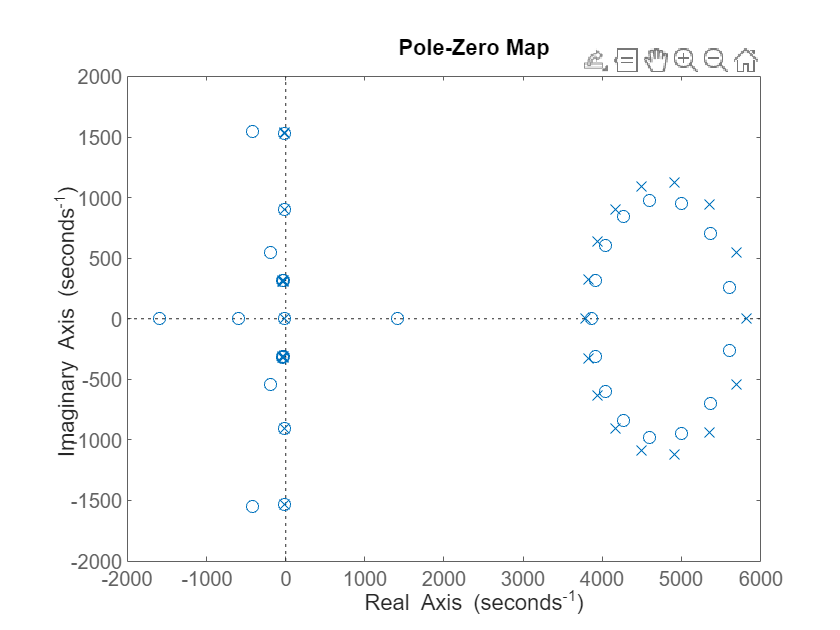


pzmap(G_Pref_Pvsc)

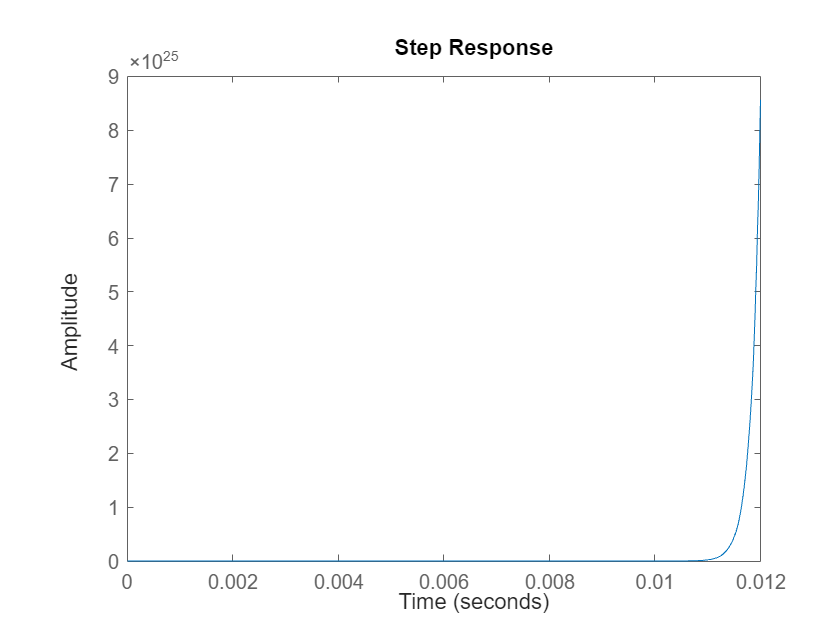

step(T_Pref_Pvsc*0.1)

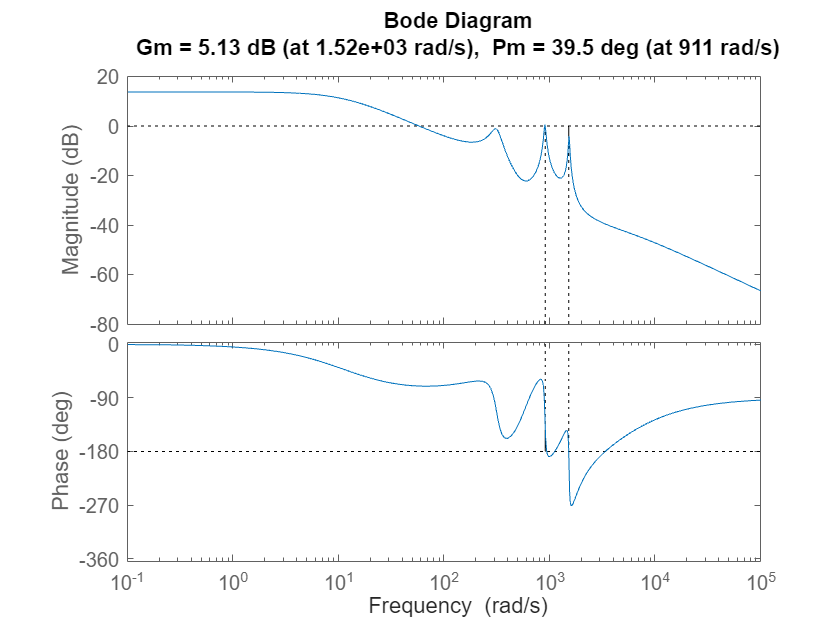

margin(G_Pref_Pvsc)